# System Identification and Model Predictive Control (MPC) Design with the Arduino-Based Balancing Bi-copter 

This example demonstrates system identification and advanced control design workflows using the low-cost balancing bi-copter developed by Prof. Eniko T. Enikov from University of Arizona. [This Github repo](https://github.com/eenikov/Arduino-based-bi-copter-experiments/tree/main) contains all the necessary files to build the bi-copter including 3D printing and assembly instructions, bill of materials as well as MATLAB code and Simulink models for running experiments for system identification and controller design using PID and state-space based approaches. This example further extends this workflow by introducing a more advanced control technique: Model predictive control with a data-driven prediction model.

## Hardware overview

The balancing bi-copter is essentially a propeller-driven pendulum that pivots around a vertical arm. There’s a small DC motor at each end of the beam driving the propellers. These motors generate thrust to control the pendulum’s angle and keep it at desired setpoint. An Arduino Nano 33 IoT board is used along with a motor driver supplying PWM voltage to drive the motors. Bi-copter's angular velocity is measured using the onboard IMU sensor. Power is supplied by the batteries housed in a battery holder beneath the board, making the setup fully portable. The IoT capability of the Arduino board allows a wireless operation of the bi-copter after deployment.

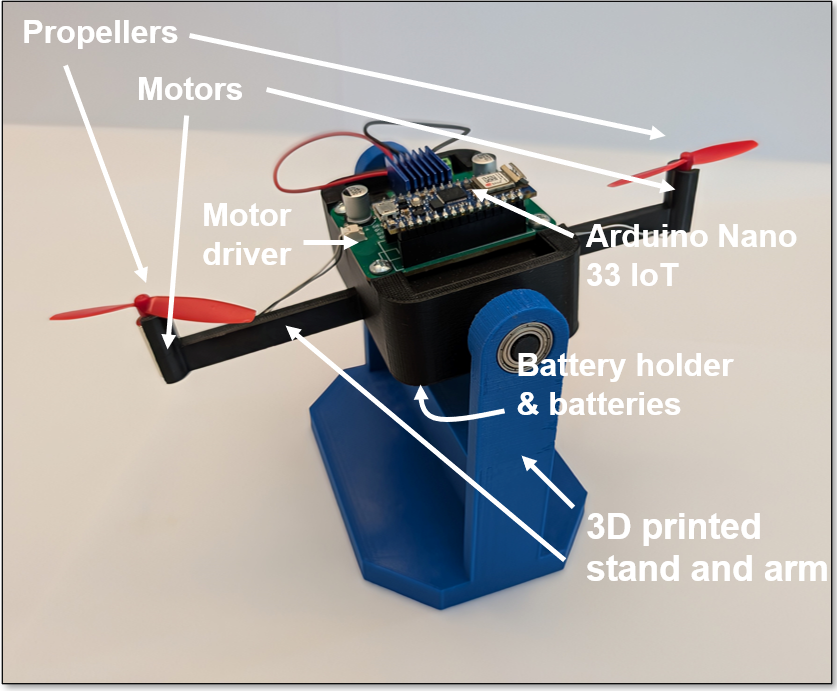

## Workflow

The below image shows the MPC design and deployment workflow including the steps for creating data-driven predictive model for MPC through system identification.

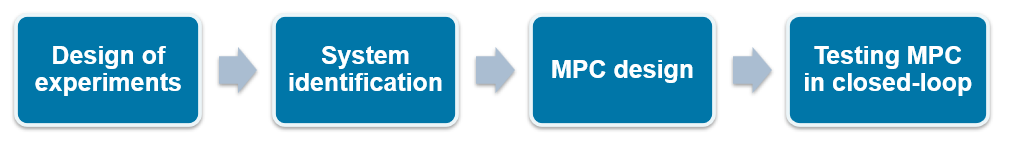

## Design of experiments 

Generate a random binary input.

clear all; 
length = 100;
Input = idinput(length, 'rbs', [0 1/30], [-7 7]); %Generate random binary input signal
plot(Input);
ylabel("Amplitude");
xlabel("# of Samples");

Deploy open-loop model and update IPADRR with the assigned IP to Arduino, which can be viewed in the Diagnostic Viewer upon deployment.

% Run experiment to gather input-output data for system identification
IPADRR = '192.168.1.27'; % Update this with the assigned IP to Arduino 
clear tcp
tcp = tcpclient(IPADRR,25000);
write(tcp,0,"int8");
pause(1);
write(tcp,Input,'int8');
flush(tcp);
en = 0;
while en == 0
    dat = read(tcp,2,'double'); % read outputs from Simulink model
    en = dat(2);
end
D = read(tcp,2*length,'double');
Output_ol = D(1:2:end);
en = D(2:2:end); 
clear tcp
pause(5)

Split measured data for model estimation and validation. Plot input-output data for both.

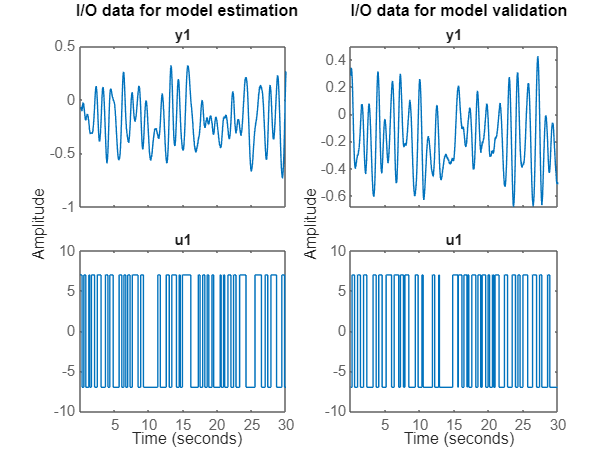

Ts = 0.01; %Sample time
data = iddata(Output_ol(1:3000)',Input(1:3000),'Ts',Ts); % Input-output data for system identification
validation_data = iddata(Output_ol(3001:6000)',Input(3001:6000),'Ts',Ts); % Input-output data for validation
close all;
subplot(1,2,1);
plot(data)
title("I/O data for model estimation")
subplot(1,2,2);
plot(validation_data)
title("I/O data for model validation")

## System identification

Preprocess data for system identification.

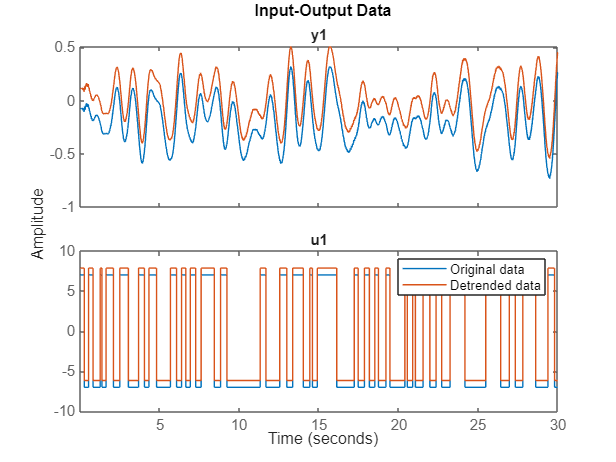

figure
plot(data); hold on;
data_preprocessed = detrend(data);
plot(data_preprocessed);
legend('Original data','Detrended data');

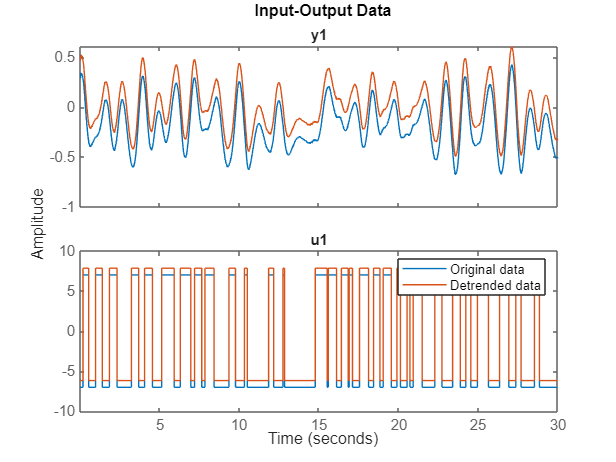

figure;
plot(validation_data); hold on;
validation_data_preprocessed = detrend(validation_data);
plot(validation_data_preprocessed);
legend('Original data','Detrended data');

Fitting a state-space model to the data.

identified_model = ssest(data_preprocessed,5,'Ts',0.01);

Compare estimated model against validation data.

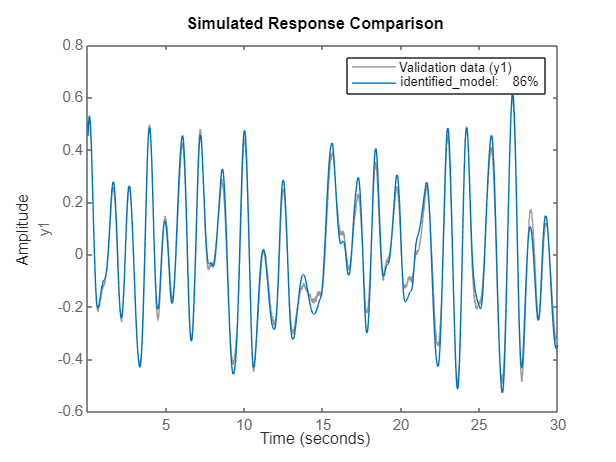

figure;
compare(validation_data_preprocessed,identified_model);

Examine open-loop system response using estimated model.

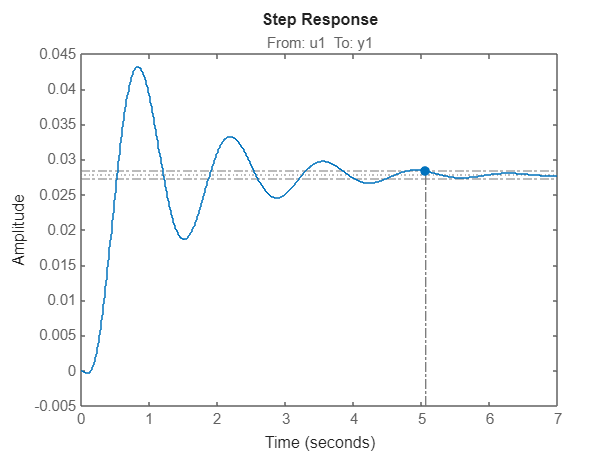

step(identified_model);

## MPC design 

Using the identified model as the prediction model for MPC, design a model predictive controller. Here, after creating the controller with the specified design parameters, we use [the MPC Designer App](https://www.mathworks.com/help/mpc/ref/mpcdesigner-app.html) for fine-tuning.

% Specify MPC parameters
sampleTime = 0.01;
predictionHorizon = 40;
controlHorizon = 2;

% Create a model predictive controller with the parameters specified above 
mpc1 = mpc(identified_model,sampleTime,predictionHorizon,controlHorizon);

-->Converting linear model from System Identification Toolbox to state-space.
-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.


% Specify MV constraints 
mpc1.ManipulatedVariables.Min = -80;
mpc1.ManipulatedVariables.Max = 80;

% The default active-set solver is used for solving the QP problem
mpc1.Optimizer.Solver

ans = 'active-set'


% Perform fine-tuning in the MPC Designer app
mpcDesigner(mpc1);

## Testing the designed MPC in closed-loop

For testing the designed MPC, deploy the closed-loop model to Arduino first. 

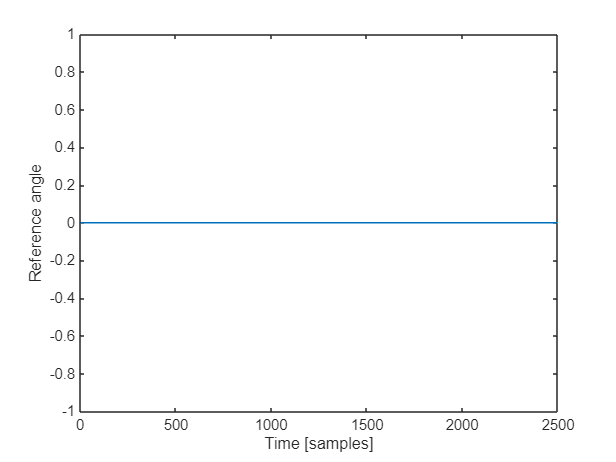

% Generate three-level square wave reference signal
length = 2500;
Ref = zeros(length,1);
Ref(501:1000) = -0.30;
Ref(1501:2000) = 0.30;
plot(Ref);
xlabel("Time [samples]");ylabel("Reference angle");

% Run experiment to test the designed MPC in closed-loop
IPADRR = '192.168.1.27'; %typically IP address remains unchanged after deployment of closed-loop model
clear tcp;
tcp = tcpclient(IPADRR,25000);
write(tcp,0,'single');
pause(5);
flush(tcp);
write(tcp,Ref,'single');
en = 0;
while en == 0
    dat = read(tcp,4,'double');
    en = dat(4);
end
D = read(tcp,4*length,'double');
Output_cl = D(1:4:end);
Control = D(2:4:end);
SP = D(3:4:end);
en = D(4:4:end);
clear tcp

Results show that the controller achieves good reference tracking, keeping the bi-copter at the reference trajectory.

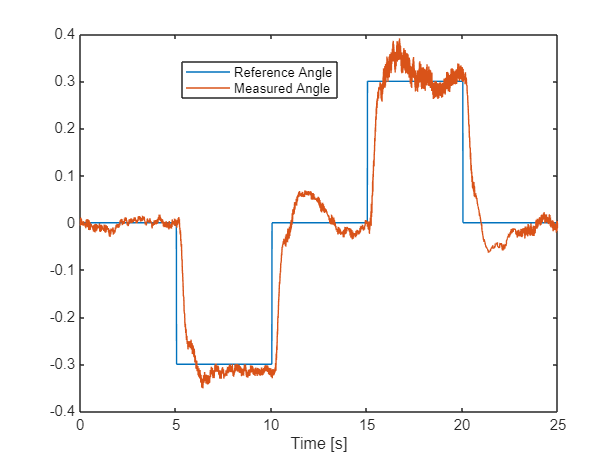

figure
Time = 0:0.01:0.01*(length-1);
plot(Time, SP);
hold on;
plot(Time, Output_cl);
legend('Reference Angle','Measured Angle');
xlabel('Time [s]');

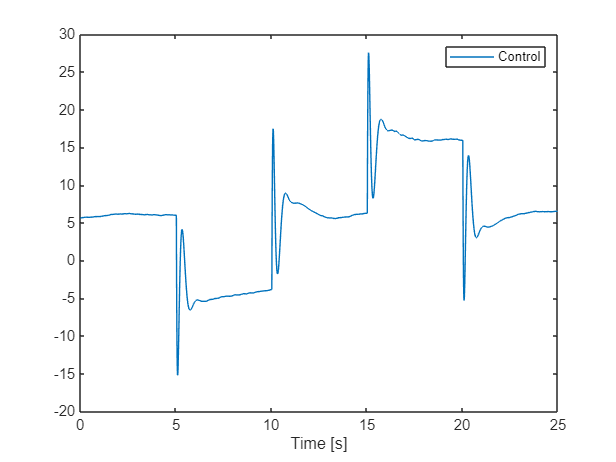

figure;
plot(Time, Control);
legend('Control');
xlabel('Time [s]');

Copyright 2025 The MathWorks, Inc.